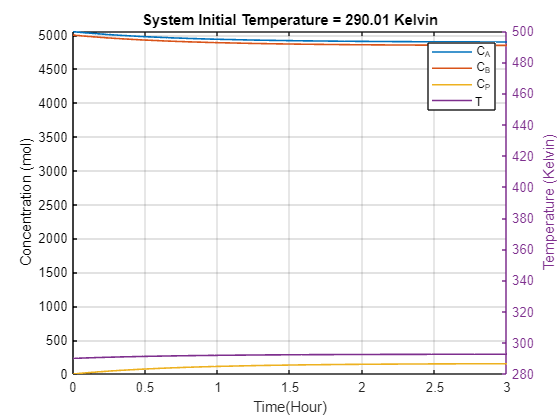

Calculation for Ti= 290.01(K) is finished. You can check the results


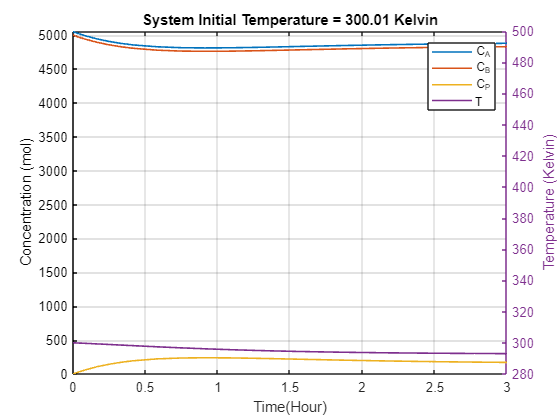

Calculation for Ti= 300.01(K) is finished. You can check the results


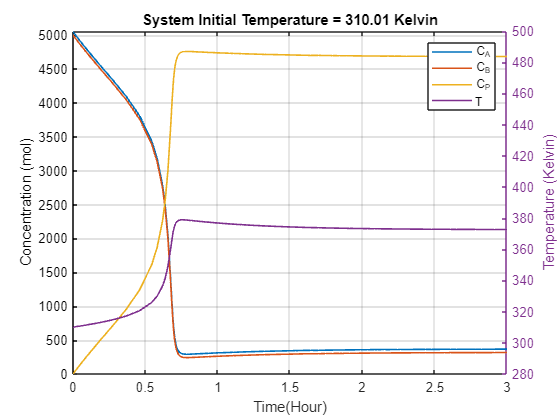

Calculation for Ti= 310.01(K) is finished. You can check the results


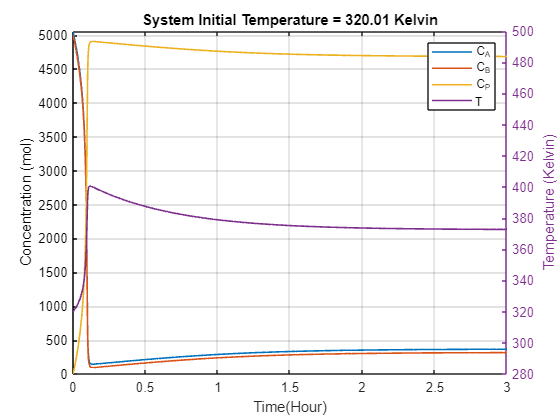

Calculation for Ti= 320.01(K) is finished. You can check the results


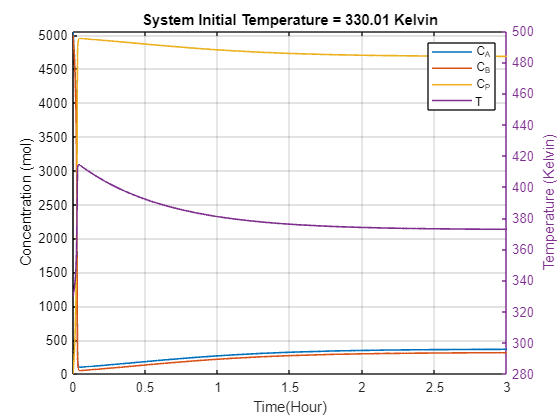

Calculation for Ti= 330.01(K) is finished. You can check the results


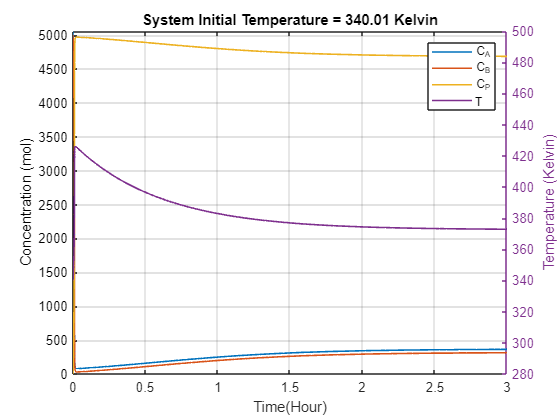

Calculation for Ti= 340.01(K) is finished. You can check the results


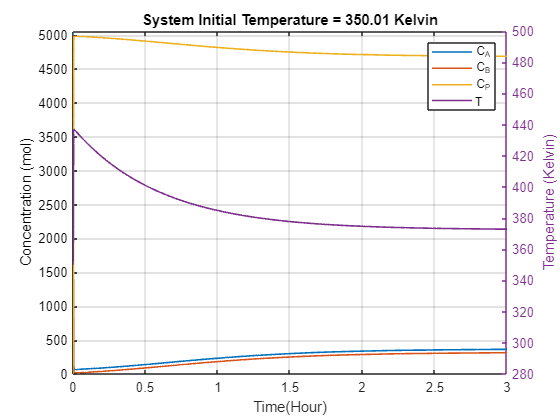

Calculation for Ti= 350.01(K) is finished. You can check the results


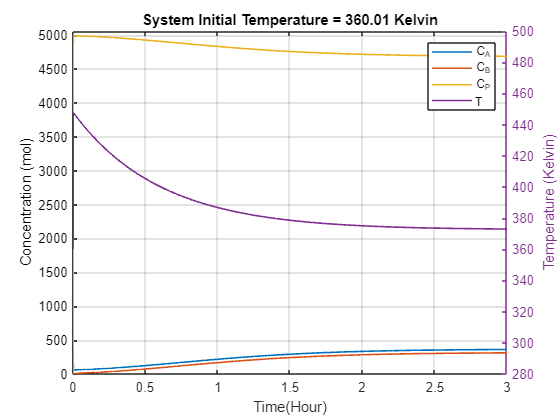

Calculation for Ti= 360.01(K) is finished. You can check the results


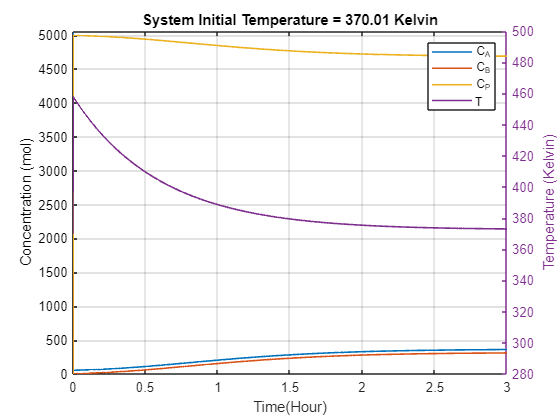

Calculation for Ti= 370.01(K) is finished. You can check the results


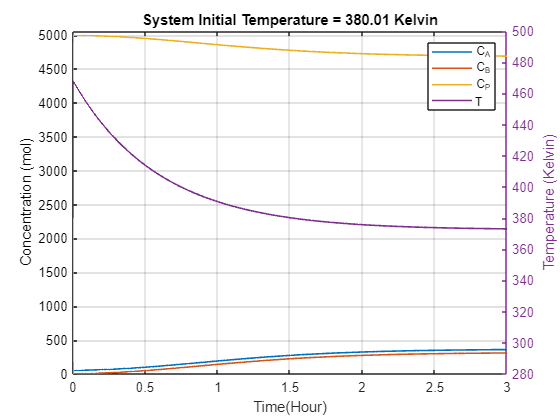

Calculation for Ti= 380.01(K) is finished. You can check the results


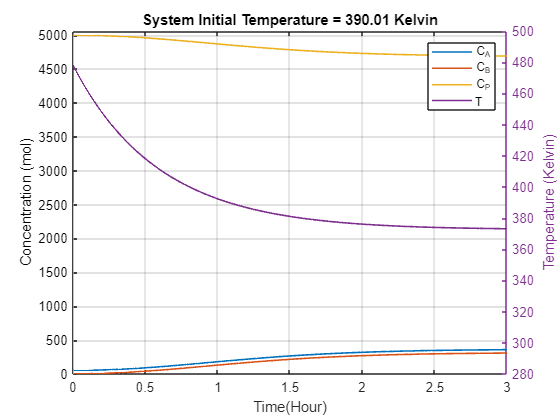

Calculation for Ti= 390.01(K) is finished. You can check the results


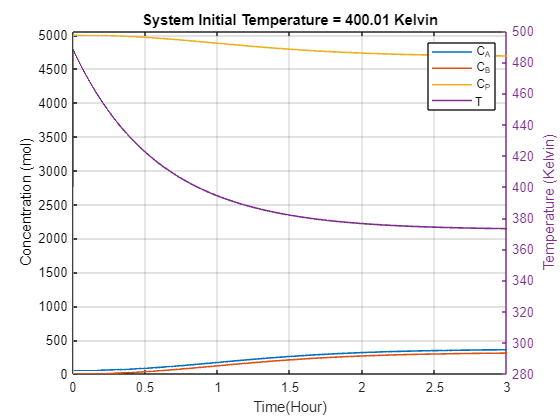

Calculation for Ti= 400.01(K) is finished. You can check the results


clc
clear all
close all
obj.C_A0 = 5050; %mol/m3 Feed concentrations
obj.C_B0 = 5000; %mol/m3 Feed concentrations
obj.C_P0 = 0; %mol/m3 Feed concentrations
obj.V_R = 1.20; %m3 Reactor volume
obj.V_f = 0.6e-3; %m3/s Volumetric flow rate 
obj.E = 99000; %J/mol Activation energy 
obj.A = 1.52e9; % m3/(mol.s) Frequency factor
obj.deltaH_r=-33.5e3; % Reaction enthalpy
obj.rho__c_p = 1900e3; % J/(m3K) Heat capacity

obj.R = 8.314; %

obj.T0 = 290;%K feed Temperature
obj.Ti = 312; %K System initial Temperature

tspan = [0, 10800]';
loopT = 290.01:10:400.01;
% loopT = 301.01:1:309.01;
% loopT = 308.1:0.1:309.9;
% loopT = 308.31:0.01:308.39;
for i = 1:length(loopT)
    clear results
    clear fig
    obj.Ti = loopT(i);
    results = ode113(@(t,y) odefun(t, y, obj), tspan, [obj.C_A0, obj.C_B0, obj.C_P0, obj.Ti]);
    results.xH = results.x/3600;

    fig = figure();
    plot(results.xH, results.y(1:3,:), 'LineWidth', 1.2);
    ylabel('Concentration (mol)')
    ylim([0, 5060])
    yyaxis right;
    plot(results.xH, results.y(4,:), 'LineWidth', 1.2);
    ylabel('Temperature (Kelvin)')
    ylim([280, 500])
    legend('C_A', 'C_B', 'C_P', 'T')
    xlabel('Time(Hour)')
    title(['System Initial Temperature = ', num2str(obj.Ti), ' Kelvin'])
    grid on
    print(fig,['T=', num2str(obj.Ti) , '.png'],'-dpng','-r1500');
    writematrix([round(results.x,4); round(results.y,2)]', ['T=', num2str(obj.Ti) , '.csv']); % Time, C_A, C_B, C_P, T
    disp(['Calculation for Ti= ', num2str(loopT(i)), '(K) is finished. You can check the results'])

end

function dydt = odefun(t,y, obj)
    C_A = y(1);
    C_B = y(2);
    C_P = y(3);
    T = y(4);
    
    k = obj.A* exp(- obj.E / (obj.R*T));
    r = k * C_A * C_B;
    dydt(1,1) = obj.V_f / obj.V_R * (obj.C_A0 - C_A) - r;
    dydt(2,1) = obj.V_f / obj.V_R * (obj.C_B0 - C_B) - r;
    dydt(3,1) = obj.V_f / obj.V_R * (obj.C_P0 - C_P) + r;

    dydt(4,1) =(obj.V_f/obj.V_R) * (obj.T0 - T) - (obj.deltaH_r * k * C_A * C_B)/(obj.rho__c_p);
    
end